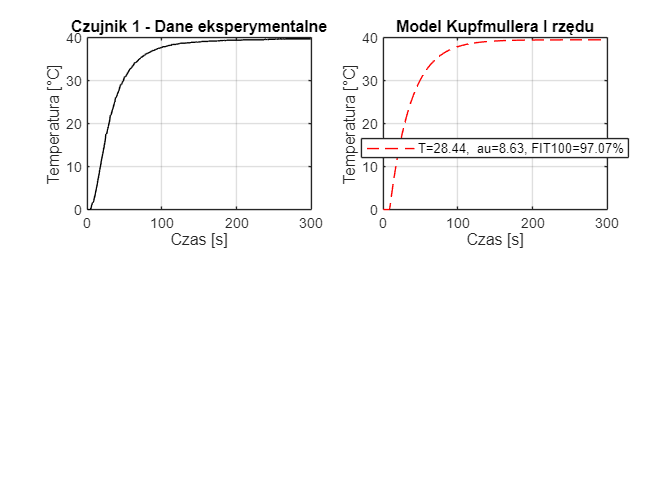


Czujnik 1:


k = 39.4840, T = 28.4364, tau = 8.6303


MSE = 25.6237, FIT100 = 97.07%


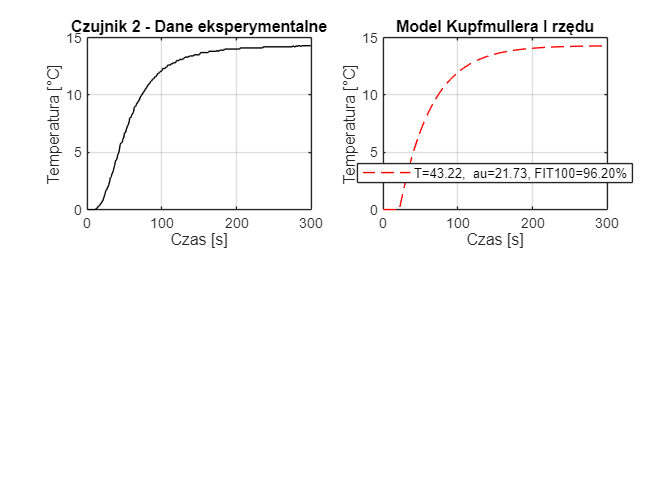


Czujnik 2:


k = 14.3029, T = 43.2216, tau = 21.7318


MSE = 8.9280, FIT100 = 96.20%


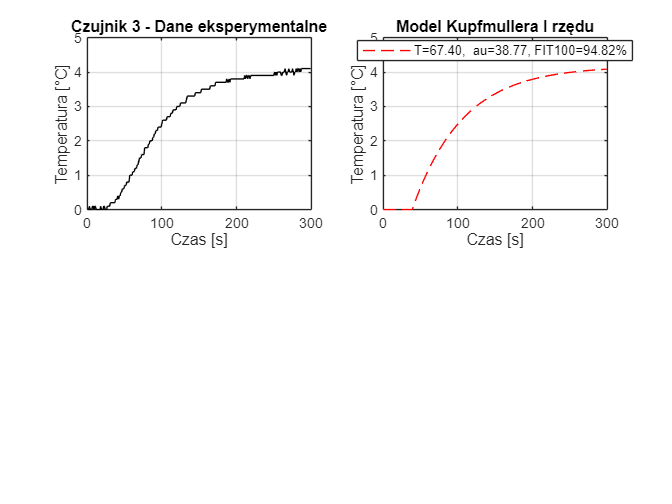


Czujnik 3:


k = 4.1698, T = 67.4032, tau = 38.7705


MSE = 1.7531, FIT100 = 94.82%


% ------------------------------
% Model Kupfmullera I rzędu z opóźnieniem
% ------------------------------

clear; clc; close all;
load piecyk_3_cels.mat
czas = 0:1:299;
u = ones(length(czas), 1);
kolory = ['r', 'g', 'b'];
nazwy = {'Czujnik 1', 'Czujnik 2', 'Czujnik 3'};

for i = 1:3
    % Dane i normalizacja
    y = piecyk_3_cels(:, i);
    y = y - y(1);
    k_static = y(end);

    % Estymacja parametrów: [k, T, tau]
    [param, mse] = fminsearch(@(X) ident_Kupf1(X, y, czas), [k_static, 40, 10]);
    K = param(1); T = param(2); tau = param(3);

    % Model i odpowiedź skokowa
    model = tf(K, [T, 1], 'OutputDelay', tau);
    ym = step(model, czas);

    % Porównanie z danymi – FIT100
    Ye = iddata(y, u, 1);
    model_id = idtf(model);
    [~, fit, ~] = compare(Ye, model_id);

    % Wykresy
    figure;
    subplot(2,2,1);
    plot(czas, y, 'k');
    title([nazwy{i} ' - Dane eksperymentalne']); grid on;
    xlabel('Czas [s]'); ylabel('Temperatura [°C]');

    subplot(2,2,2);
    plot(czas, ym, 'r--');
    legenda = sprintf('T=%.2f, \tau=%.2f, FIT100=%.2f%%', T, tau, fit);
    title('Model Kupfmullera I rzędu');
    legend(legenda, 'Location', 'best'); grid on;
    xlabel('Czas [s]'); ylabel('Temperatura [°C]');

    fprintf("\nCzujnik %d:\n", i);
    fprintf("k = %.4f, T = %.4f, tau = %.4f\n", K, T, tau);
    fprintf("MSE = %.4f, FIT100 = %.2f%%\n", mse, fit);
end


function blad = ident_Kupf1(X, y, t)
    K = X(1); T = X(2); tau = X(3);
    if K < 0 || T <= 0 || tau < 0
        blad = inf; return;
    end
    model = tf(K, [T, 1], 'OutputDelay', tau);
    ym = step(model, t);
    blad = sum((y(:) - ym(:)).^2);
end
